# Análisis de Datos (Titanic)

#  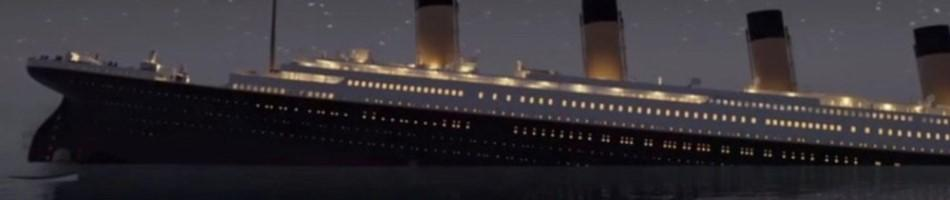

####     Paso 1 : Carga de Datos

% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ",";

% Specify column names and types
opts2.VariableNames = ["PassengerId", "Survived", "Pclass", "Name", "Sex", "Age", "SibSp", "Parch", "Ticket", "Fare", "Cabin", "Embarked"];
opts2.VariableTypes = ["double", "double", "double", "string", "categorical", "double", "double", "double", "double", "double", "string", "categorical"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Specify variable properties
opts2 = setvaropts(opts2, ["Name", "Cabin"], "WhitespaceRule", "preserve");
opts2 = setvaropts(opts2, ["Name", "Sex", "Cabin", "Embarked"], "EmptyFieldRule", "auto");

% Import the data
titanic = readtable("C:\Users\MarcoA\Documents\MATLAB\u_sabana\titanic_dataset.csv", opts2);

% Clear temporary variables
clear opts2

% Display results
titanic

titanic = 891×12 table
    PassengerId    Survived    Pclass                            Name                              Sex      Age    SibSp    Parch      Ticket       Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ______    ___    _____    _____    __________    ______    ______    ________

         1            0          3       "Braund, Mr. Owen Harris"                                male       22      1        0             NaN      7.25    ""           S    
         2            1          1      

#### Paso 2: Exploración inicial de los datos

% Ver cuántos valores faltantes hay en cada columna
missing = sum(ismissing(titanic)) 

missing =      0     0     0     0     0   177     0     0   230     0     0     2


#### Paso 3 :  Limpieza de los Datos

Sobre el archivo podemos ver

- Tiene un total de 12 columnas como Id del pasajero, sexo, edad, tarifa, cabina, entre otras y 891 filas

- Se tienen 3 tipos de datos Flotantes, Enteros y Strings

- Se tienen una gran cantidad de Missing Values (Nan).

- Columnas como PassengerId, Survived, Pclass, Name, Sex, SibSp, y Parch no tienen valores faltantes

- Las columnas con mayores valores faltantes pueden requeridad imputar los valores faltantes o si no sirven para el análisis excluirlos

#### Reemplazar con la Mediana sobre Age


medianaAge = median(titanic.Age, 'omitnan');
medianaAgeInt = round(medianaAge);

% Reemplazar los missing values de Age por la mediana redondeada
titanic.Age = fillmissing(titanic.Age, 'constant', medianaAgeInt);

% Convertir la columna Age a enteros (por ejemplo, int16)
%titanic.Age = int16(titanic.Age);

titanic

titanic = 891×12 table
    PassengerId    Survived    Pclass                            Name                              Sex      Age    SibSp    Parch      Ticket       Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ______    ___    _____    _____    __________    ______    ______    ________

         1            0          3       "Braund, Mr. Owen Harris"                                male      22       1        0             NaN      7.25    ""           S    
         2            1          1      

titanic = removevars(titanic, {'Cabin', 'Ticket', 'Name', 'PassengerId'})

titanic = 891×8 table
    Survived    Pclass     Sex      Age    SibSp    Parch     Fare     Embarked
    ________    ______    ______    ___    _____    _____    ______    ________

       0          3       male      22       1        0        7.25       S    
       1          1       female    38       1        0      71.283       C    
       1          3       female    26       0        0       7.925       S    
       1          1       female    35       1        0        53.1       S    
       0          3       male      35       0        0        8.05       S    
       0          3       male      28       0        0      8.4583       Q    
       0          1       male      54       0        0      51.8